# **CAN - Working with CAN FD**

This example shows how to pack and unpack CAN FD messages to be used with a Speedgoat CAN I/O module. Currently, this example can be used with the IO602, IO603 and IO691. The Simulink model implements a loopback by sending CAN FD messages from channel 1 to channel 2. 

This example demonstrates the following modes and features:

- CAN and CAN FD bus data types

- Packing and unpacking a CAN FD message based on a database file

- Packing and unpacking a CAN FD message by manually specifying a CAN FD message

- Manually creating a CAN FD message bus and accessing individual CAN FD message properties

Note: There are other available examples showcasing DIO and LIN usage with IO603 I/O Module.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with an IO602, IO603 or an IO691 CAN I/O module installed

- 1x CAN Loopback test cables with terminator resistor (120 Ω)

### Connection Diagram

To run this example, the CAN channel 1 and channel 2 must be connected with a terminated CAN cable. As this example can be executed with different IO Modules, refer to the pin mapping for your CAN I/O module:

- [IO602-4 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_4_pin_mapping)

- [IO602-2 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_2_pin_mapping)

- [IO603 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io603_pin_mapping)

- [IO691 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io691_pin_mapping)

## Open and configure the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_CAN_FDLoopback';
open_system(modelName);

### Select CAN I/O Module

In the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block, select the specific CAN I/O module that you are using. A unique **Module ID** is set in every [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to link the [CAN Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_read) and [CAN Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) blocks in the rest of the model to the Setup block in question. If there is only one IO602, IO603 or IO691 in the target, the **Module ID** can always remain at 1.

 
% open the CAN setup block to select your CAN I/O module
speedgoat.model.highlight([modelName '/CAN_Setup'],'Parameter','moduleType');

### Specify CAN channels

After selecting the correct CAN I/O module, channel 1 and channel 2 must be configured for the CAN FD operating mode. You can do this with the dropdown in the mask or with the following code section. Unused CAN channels can be disabled.

 
% configure CAN channel 1 and 2 to CAN FD
set_param([modelName '/CAN_Setup'],'canChn1','CAN-FD');
set_param([modelName '/CAN_Setup'],'canChn2','CAN-FD');

When a channel is enabled, the baud rate can be configured in the tab that is shown for each channel. For CAN FD, two baud rates must be set in the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block, as the data part of the CAN FD frame can be transmitted at a different and usually faster rate. 

## Model Description

The model is split into three main loopback paths where the CAN FD messages are sent from channel 1 to channel 2. Additionally, the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block and a subsystem showcase the differences between the CAN and the CAN FD bus datatypes are present in the model. You already used the [CAN Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa) block to select the correct CAN I/O module and to configure the CAN channels to be used for CAN FD. A description of the datatypes and the different packing and unpacking methods is provided below.

### Describe Differences between Datatypes

 
% open the subsystem for the CAN_(FD)_MESSAGE_BUS - Datatypes
speedgoat.model.highlight([modelName '/CAN_(FD)_MESSAGE_BUS - Datatypes'],'Open',true);

This subsystem shows the two datatypes for the standard CAN messages and for the CAN FD messages. The CAN and CAN FD messages are defined using the CAN_MESSAGE_BUS and CAN_FD_MESSAGE_BUS datatypes which are [Simulink bus signals](https://mathworks.com/help/simulink/slref/simulink.bus.html), and which contain individual elements for the different properties of the message. The signals contained in the CAN_MESSAGE_BUS and the CAN_FD_MESSAGE_BUS are shown in the model, together with the description and the datatypes used for this specific signal. 

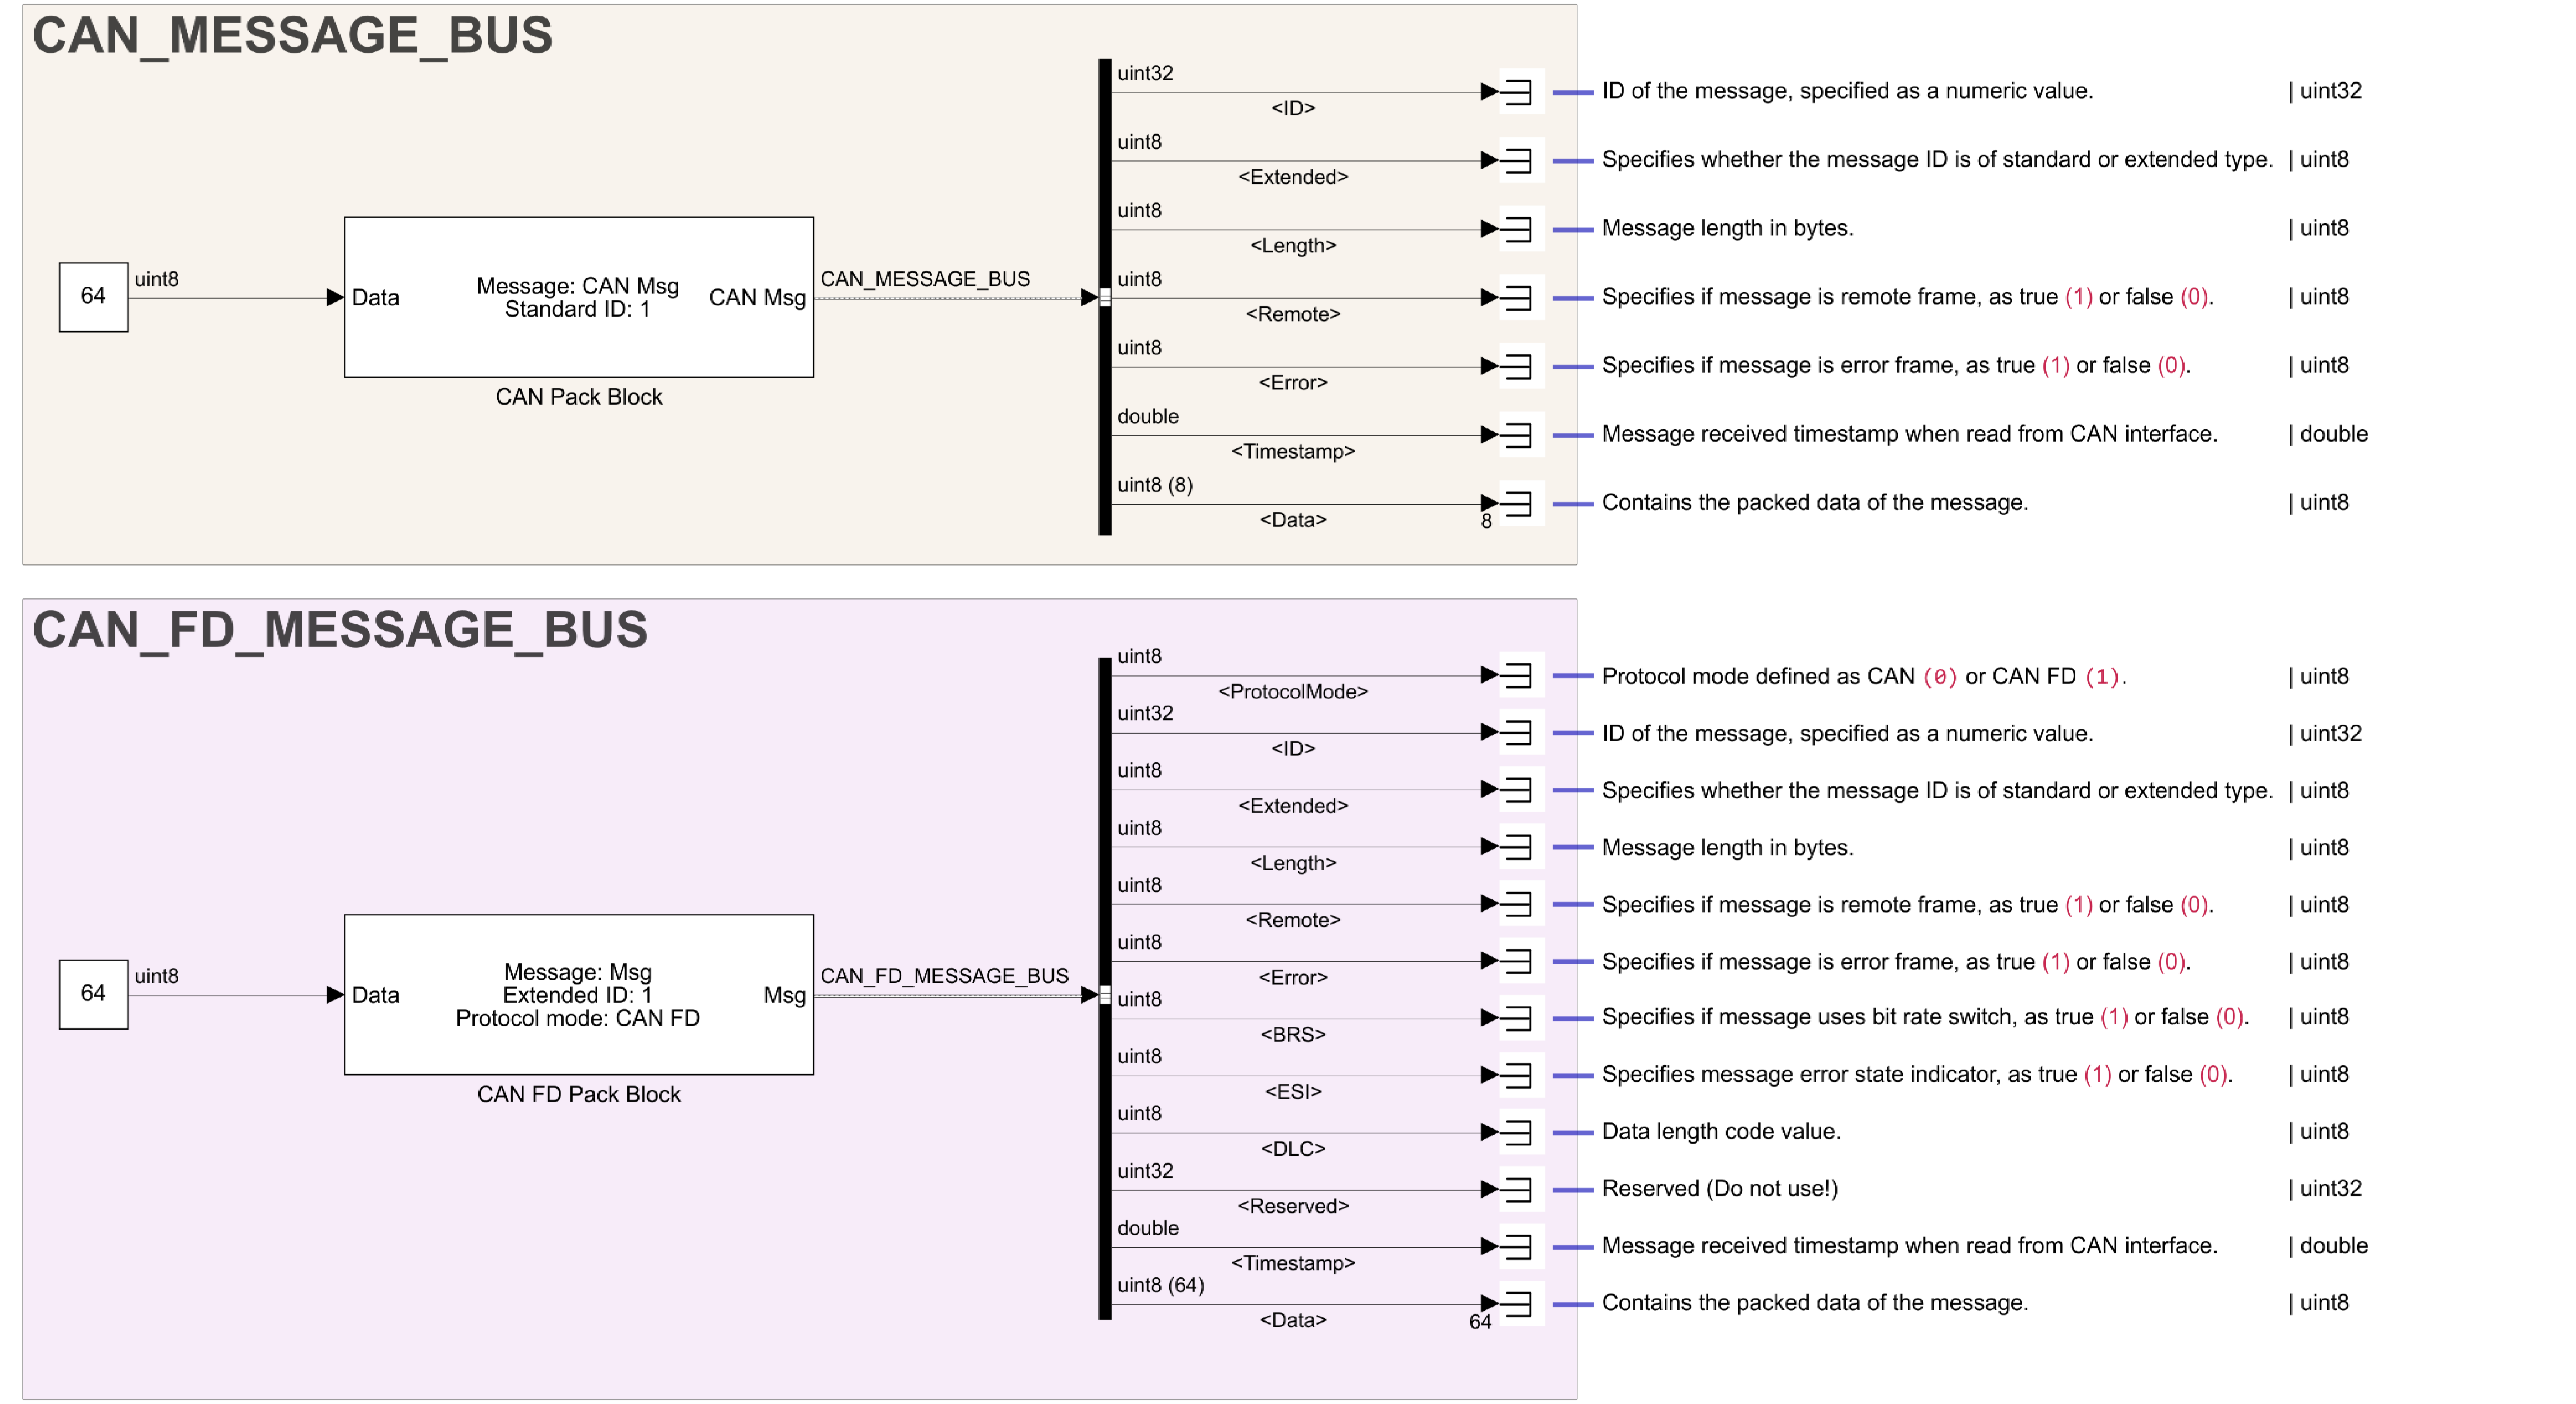

To create a bus object in the base workspace for the Simulink CAN and CAN FD message bus, refer to the MathWorks VNT documentation for [canMessageBusType](https://mathworks.com/help/vnt/ug/canfdmessagebustype.html) and [canFDMessageBusType](https://mathworks.com/help/vnt/ug/canfdmessagebustype.html).

As for the standard CAN workflow, [CAN FD Pack](https://mathworks.com/help/vnt/ug/canfdpack.html) and [CAN FD Unpack](https://mathworks.com/help/vnt/ug/canfdunpack.html) blocks are available. These blocks are available in the **Simulink Library Browser** under *Simulink Real-Time/CAN/CAN-FD MSG blocks.* They can also be found in the following block library: 

Please note that the CAN FD blocks also allow you to pack standard CAN messages as there is a dedicated element in the CAN_FD_MESSAGE_BUS that describes the protocol mode used:

 
% highlight Protocol Mode in CAN FD MESSAGE
speedgoat.model.highlight([modelName '/CAN_(FD)_MESSAGE_BUS - Datatypes/BusSelector_CANFD'],'Signal',1);

### Pack and Unpack CAN FD Messages Based on a Database File

 
% highlight area CAN FD Write Ch1 - dbc
speedgoat.model.highlight([modelName '/CAN FD Write Ch1 - dbc']);

The most straightforward way to pack and unpack a CAN FD message is by using a database file (.dbc) and the CAN FD pack/unpack blocks. In the [CAN FD Pack](https://mathworks.com/help/vnt/ug/canfdpack.html) block, select **CANdb specified signals** as the input data type. This allows you to specify your CAN database file in the edit field. In the **Message list**, all CAN messages from the .dbc files are shown and you can select the IDs you want to use with this block. All fields that are grayed out are automatically set according to the selected message. 

Two [CAN FD Pack](https://mathworks.com/help/vnt/ug/canfdpack.html) blocks are used in the model to pack the signals into the CAN FD messages. The CAN FD messages are represented in the CAN_FD_MESSAGE_BUS datatype and are grouped together with a [Vector Concatenate](https://mathworks.com/help/simulink/slref/vectorconcatenate.html) block. This allows you to send out multiple CAN FD messages with one [CAN write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block. Please note that the number of messages in the [CAN write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa_write) block must be specified in the parameter field of the same name.

 
% highlight area CAN FD Read Ch1 - dbc
speedgoat.model.highlight([modelName '/CAN FD Read Ch2 - dbc']);

Unpacking the CAN FD messages received is done in the same fashion as the [CAN FD Unpack](https://mathworks.com/help/vnt/ug/canfdunpack.html) block. Note that in this block you can select additional output ports to obtain more information about the CAN FD messages recieved (Bit Rate Switch, Timestamp, etc.).

### Pack and Unpack CAN FD Messages Based on a Database File

As mentioned above, the CAN_FD_MESSAGE_BUS datatype can be used with standard CAN messages. Standard CAN messages can also be sent and received on a CAN channel that is configured for CAN FD. This is shown in the **CAN FD Write Ch1 - standard CAN message **section:

 
% highlight area CAN FD Read Ch1 - dbc
speedgoat.model.highlight([modelName '/CAN FD Write Ch1 - standard CAN message']);

Here a [CAN FD Pack](https://mathworks.com/help/vnt/ug/canfdpack.html) block is used, but the selected message is a standard CAN message, as can be seen in the **Protocol Mode **parameter:

% highlight protocol mode in CAN FD pack block
speedgoat.model.highlight([modelName '/CAN FD Pack_standard'],'Parameter','ProtocolMode');

Since the output datatype is a bus signal, a [Bus Selector](https://mathworks.com/help/simulink/slref/busselector.html) block can be used to access the individual elements of the CAN FD message. If you check the Protocol Mode signal, you will notice the value is 0, which indicates a standard CAN message. 

The same concept applies on the receiving side. 

### Manually Create a CAN FD Message

 
% highlight area CAN FD Write Ch1 - manually create CAN FD message
speedgoat.model.highlight([modelName '/CAN FD Write Ch1 - manually create CAN & CAN FD message']);

For some applications, you may need to manually construct a CAN_FD_MESSAGE_BUS datatype (refer to the bottom left of the model). The individual elements of the CAN_FD_MESSAGE_BUS can be controlled using a subsystem and bus outports.

A [Bus Assignment](https://mathworks.com/help/simulink/slref/busassignment.html) block can also be used to overwrite an existing element of the CAN_FD_MESSAGE_BUS with another value. This is shown in the Overwrite_CAN_FD_message subsystem, where the BRS value is toggled using a pulse generator.

 
% highlight subsystem Overwrite_CAN_FD_message
speedgoat.model.highlight([modelName '/Overwrite_CAN_FD_message'],'Open',true);

To access the same CAN FD message property of multiple messages, it is best to group all the messages into a nested bus structure with a [Bus Creator](https://mathworks.com/help/simulink/slref/buscreator.html) block**. **To obtain all the timestamp values, connect a [Bus Selector](https://mathworks.com/help/simulink/slref/busselector.html) block to the nested bus and search for "timestamp", then select all timestamp signals:

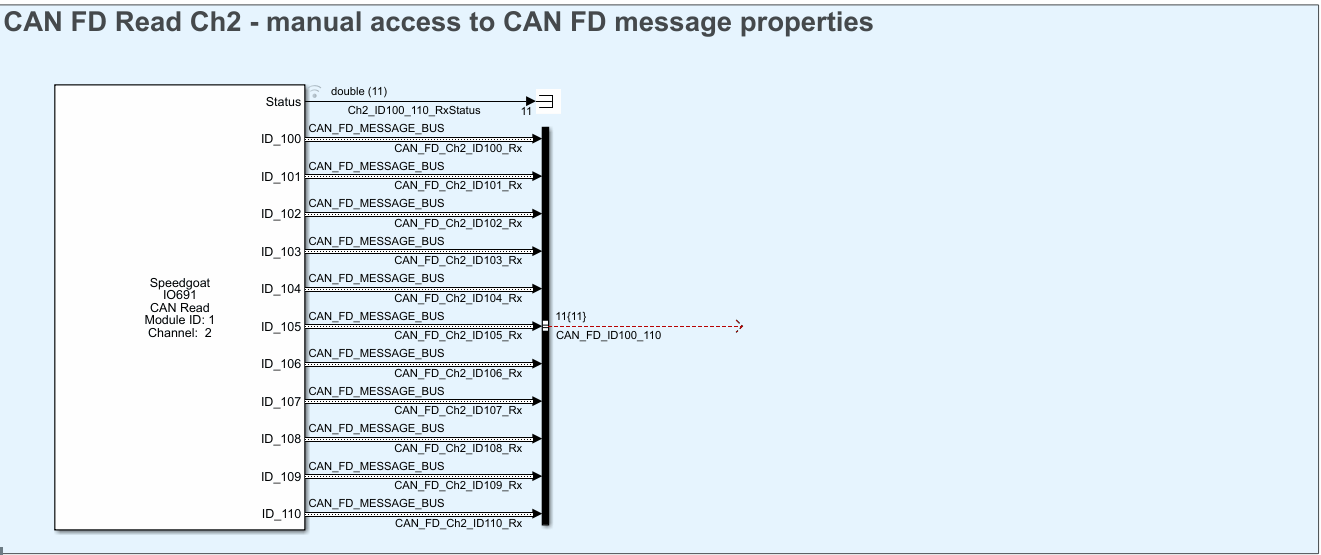

For further processing, the signals can be grouped together using a [Mux](https://mathworks.com/help/simulink/slref/mux.html) block, as shown in the above subsystem.   

 
% open subsystem to select timestamps
speedgoat.model.highlight([modelName '/Select_Timestamps'],'Open',true);

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

  
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download the real-time application to the target machine and set stop time
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
% This will allow you to use the Simulink scopes in the model to view the data
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode
set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Wait until the real-time application reaches the stop time of 10 seconds

### Results

Check the scopes for the CAN FD messages received to see if the loopback is working. The screenshots below show the expected outcome. 

You can change the parameters of the source signal blocks. Any changes should be reflected on the receiving end immediately. 

**CAN FD Read Ch2 - dbc**

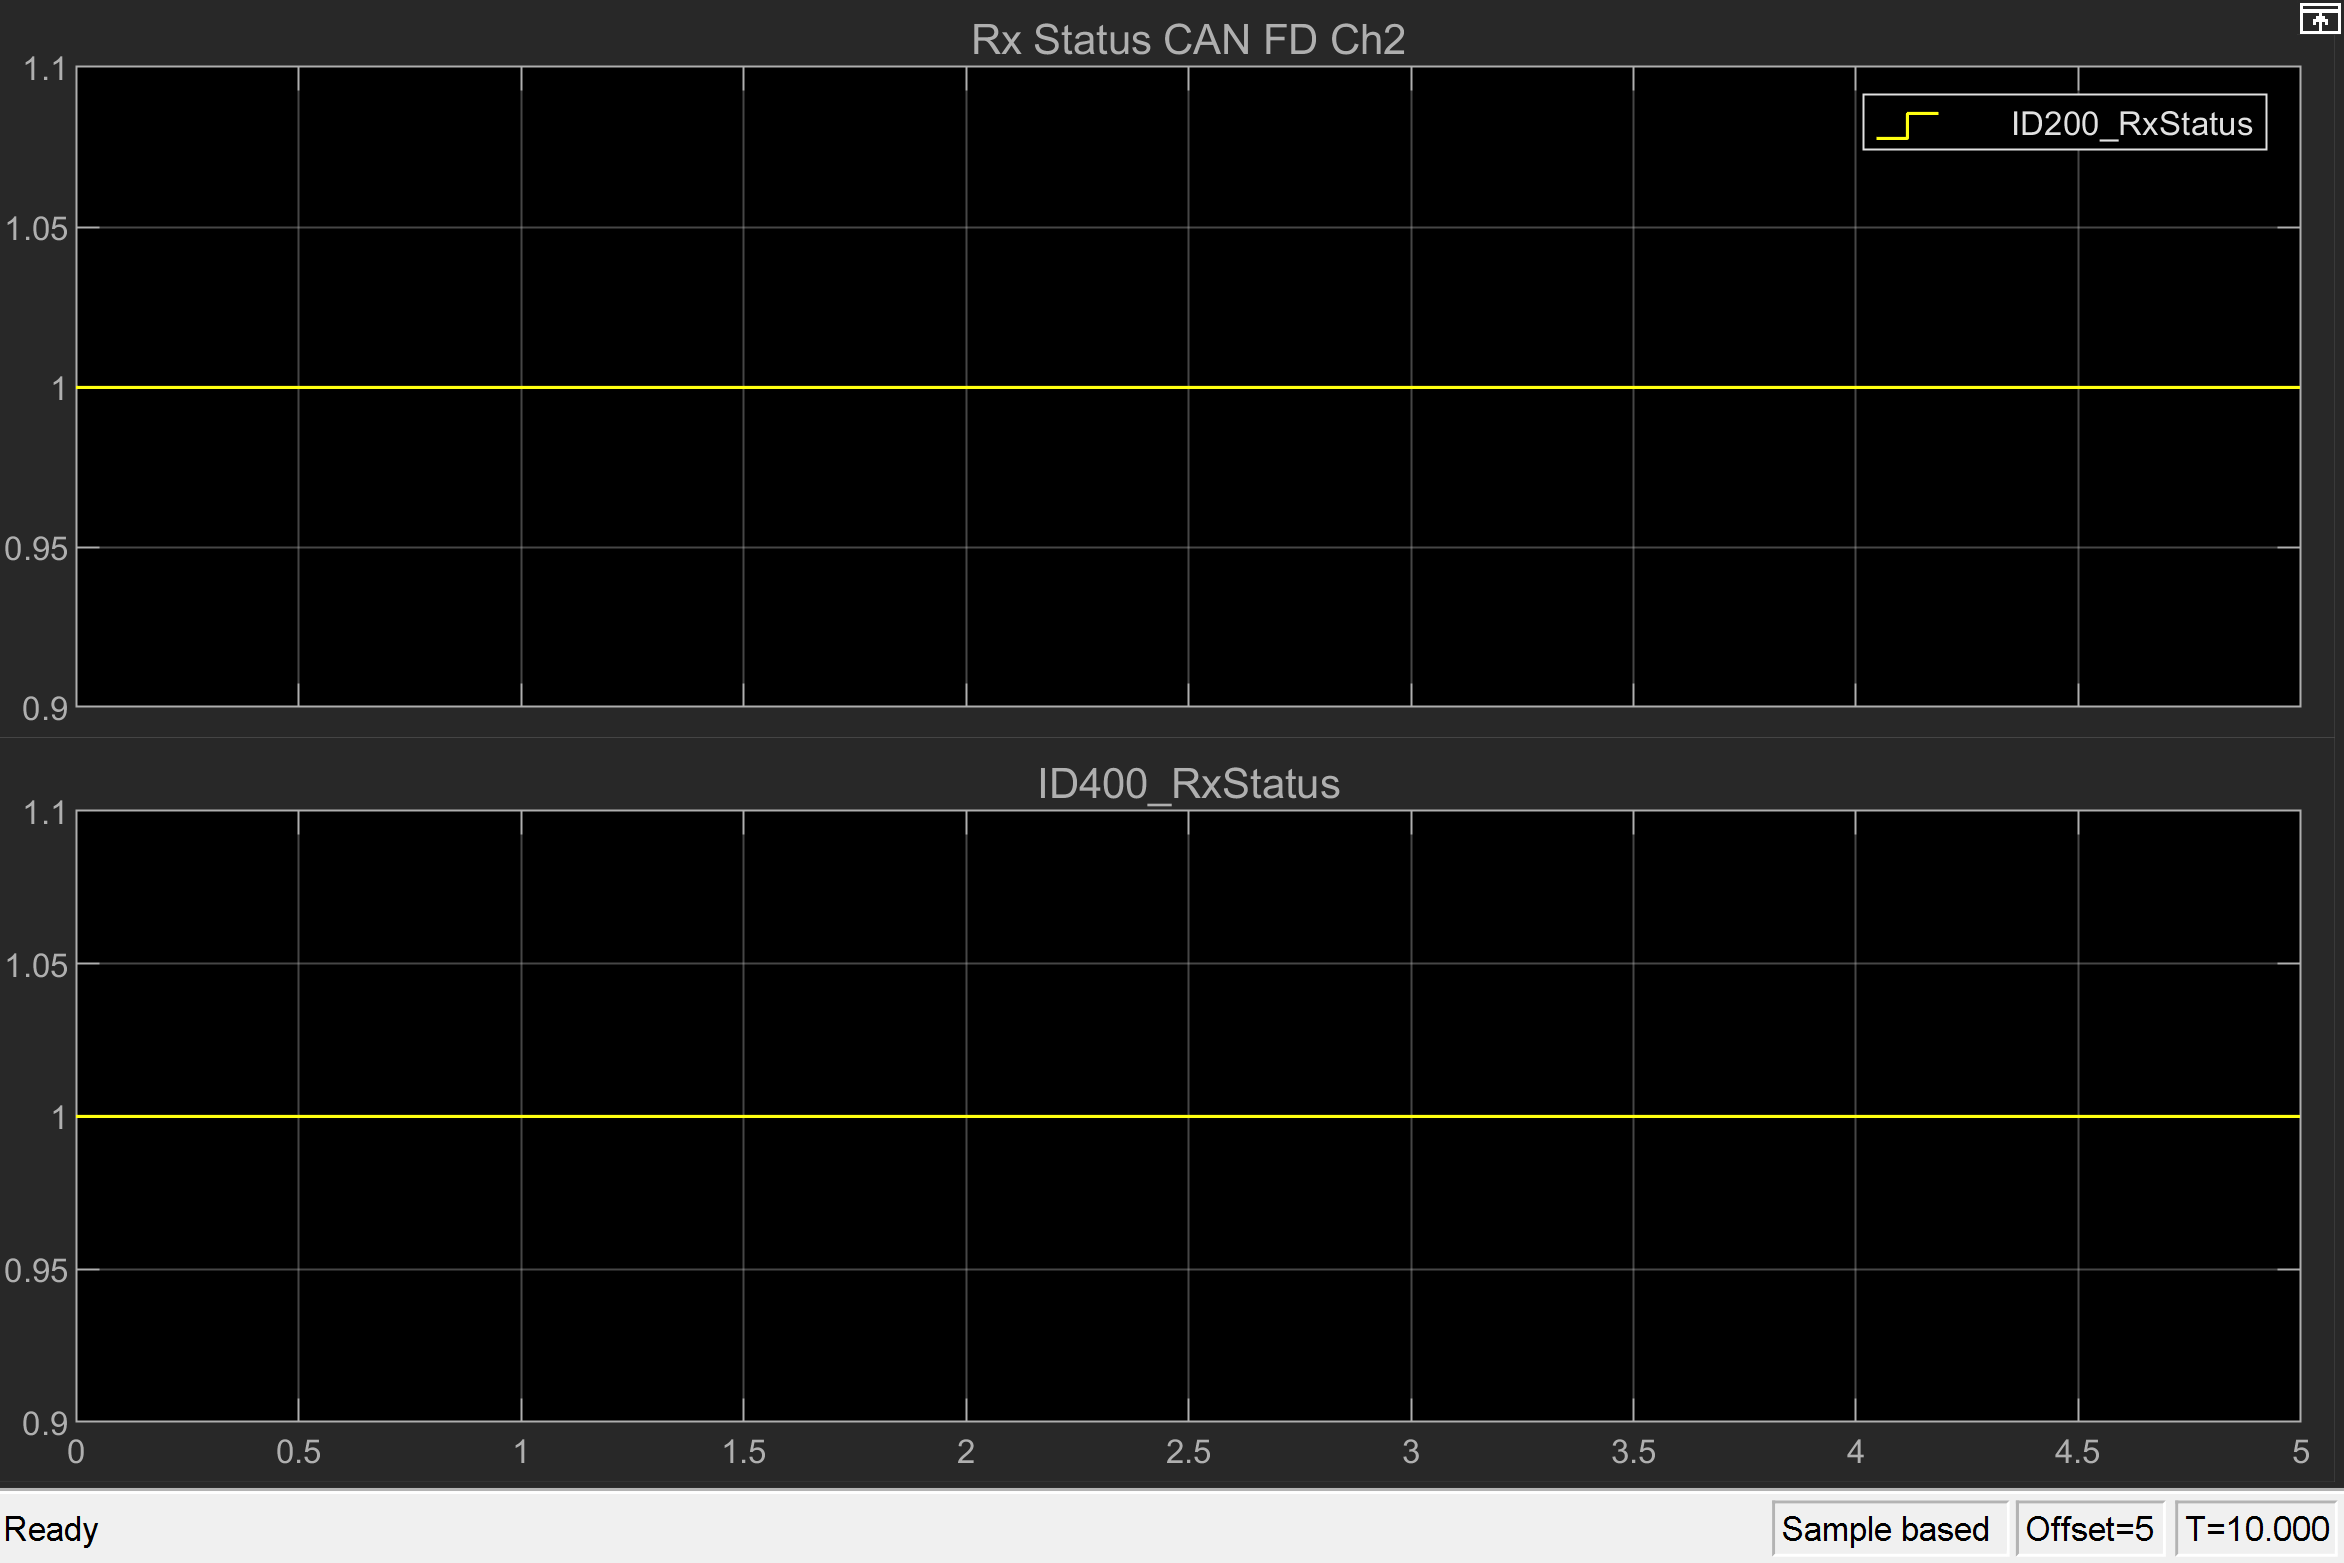 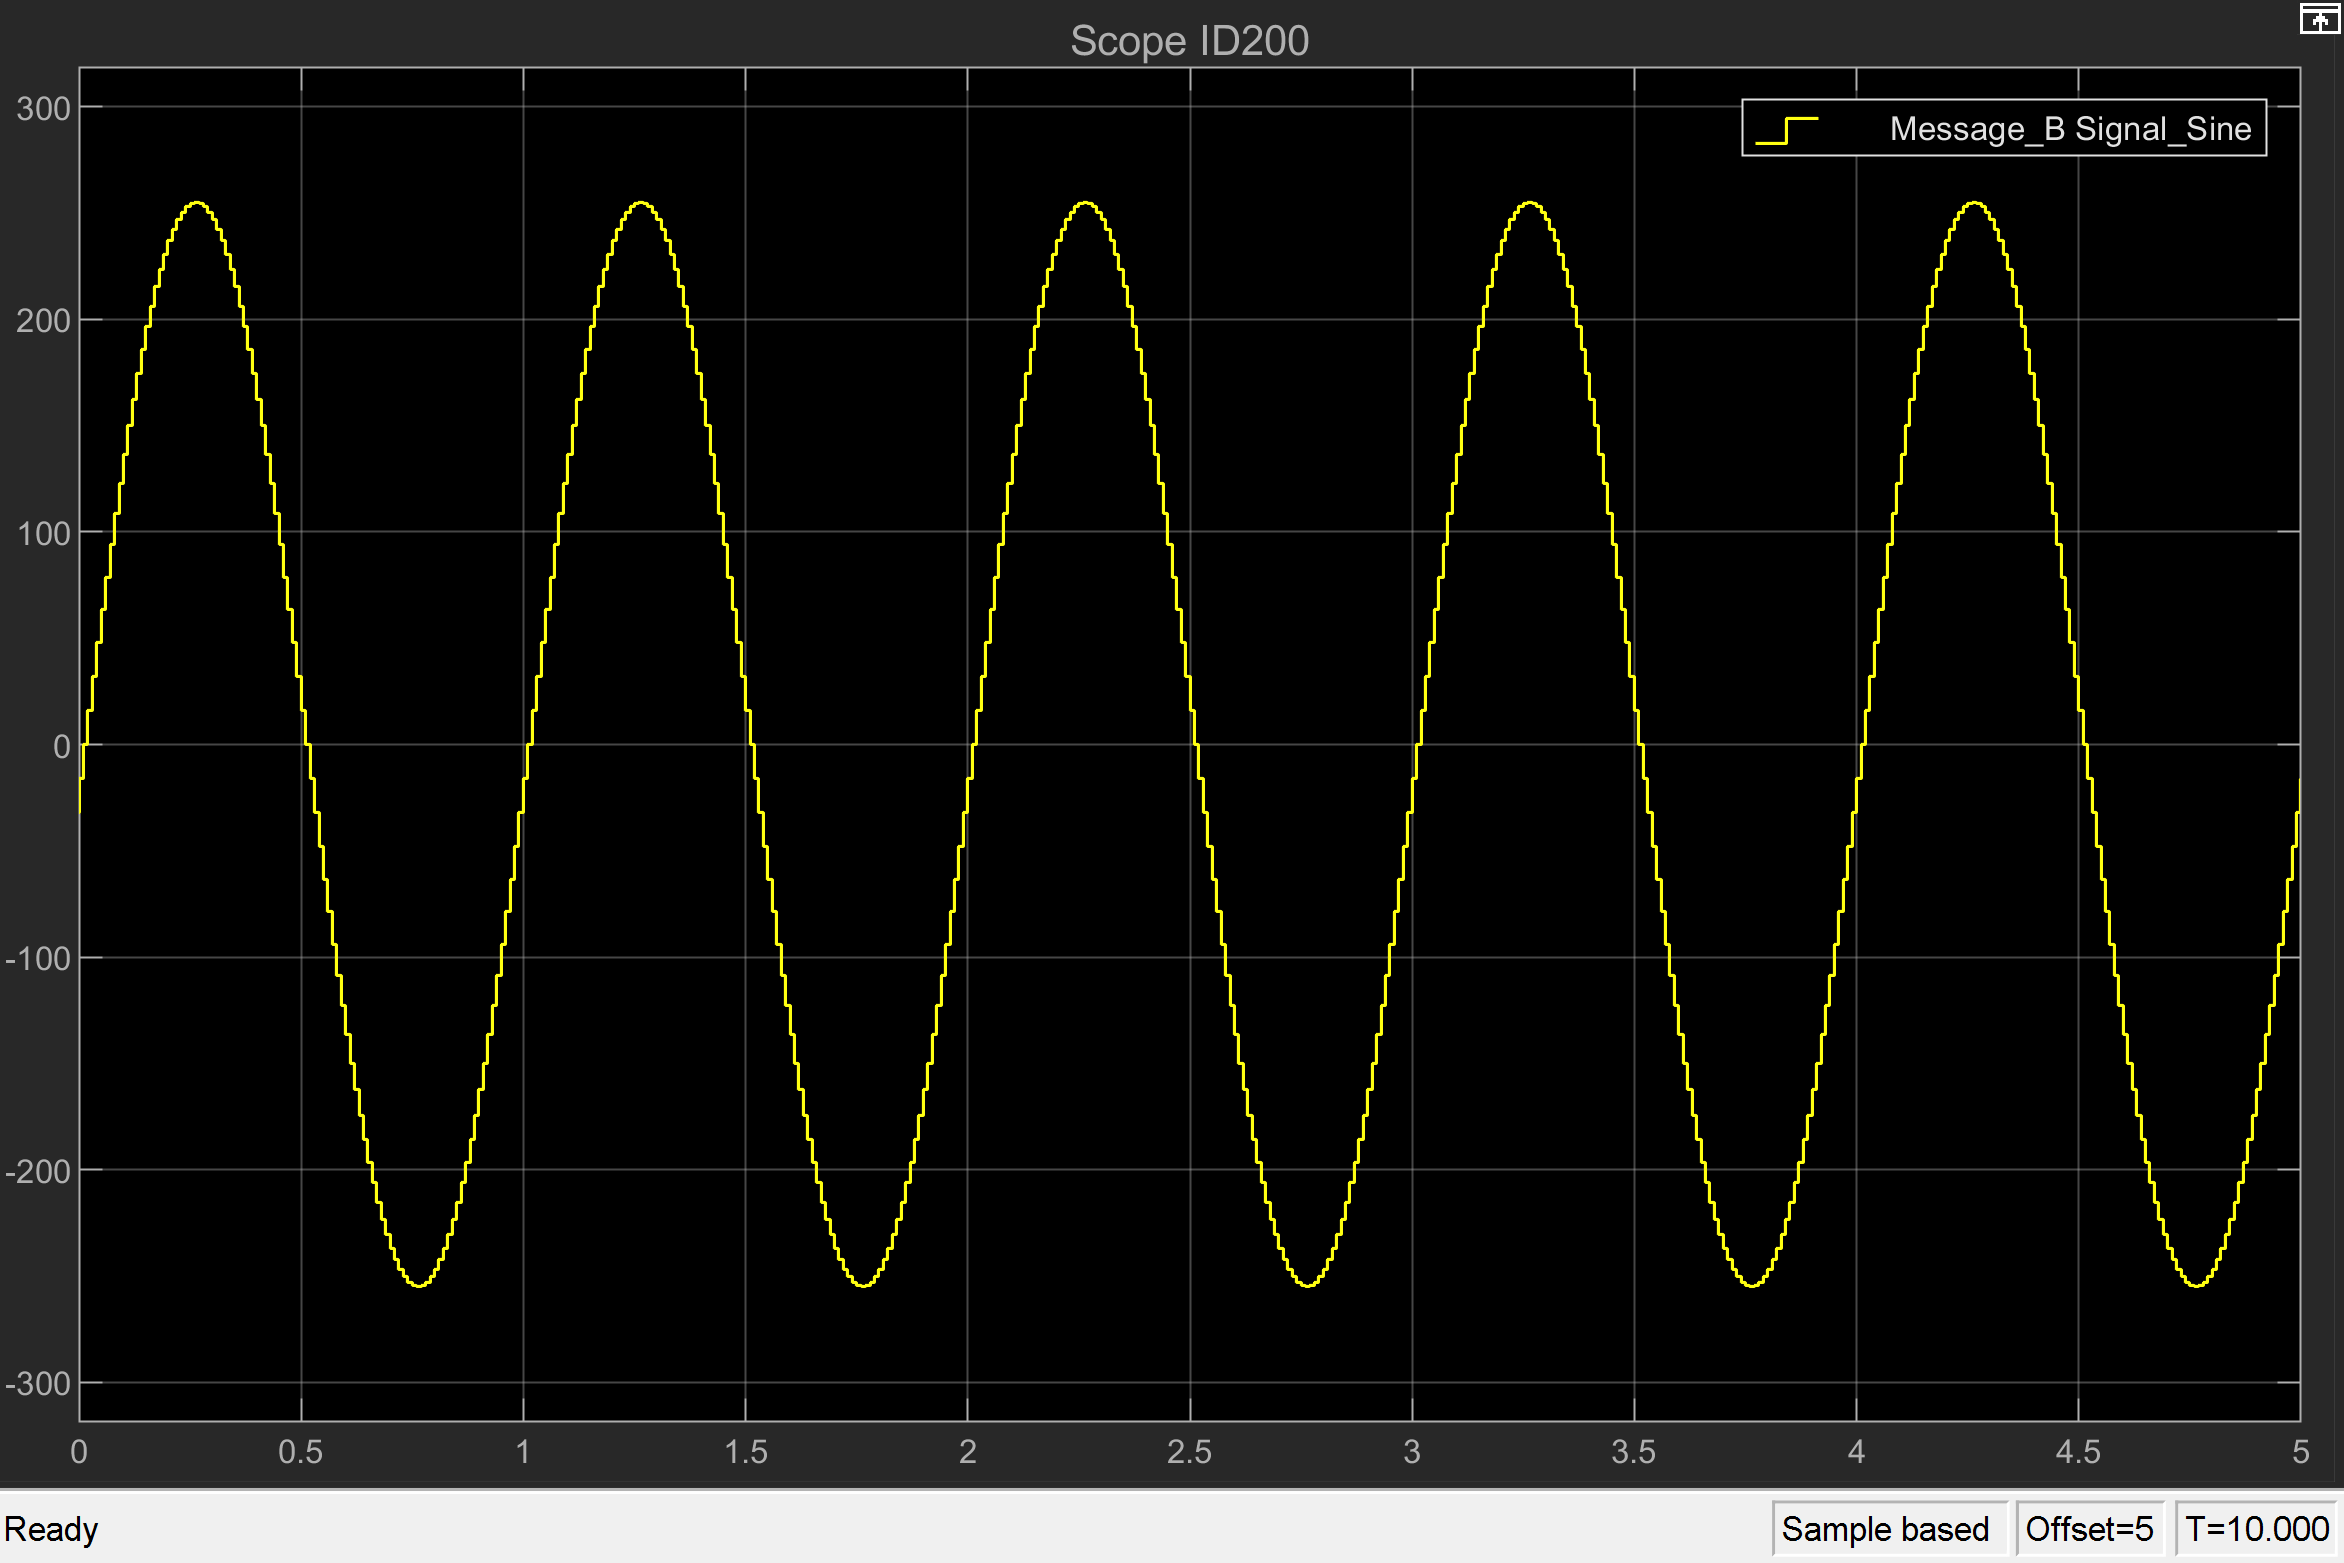   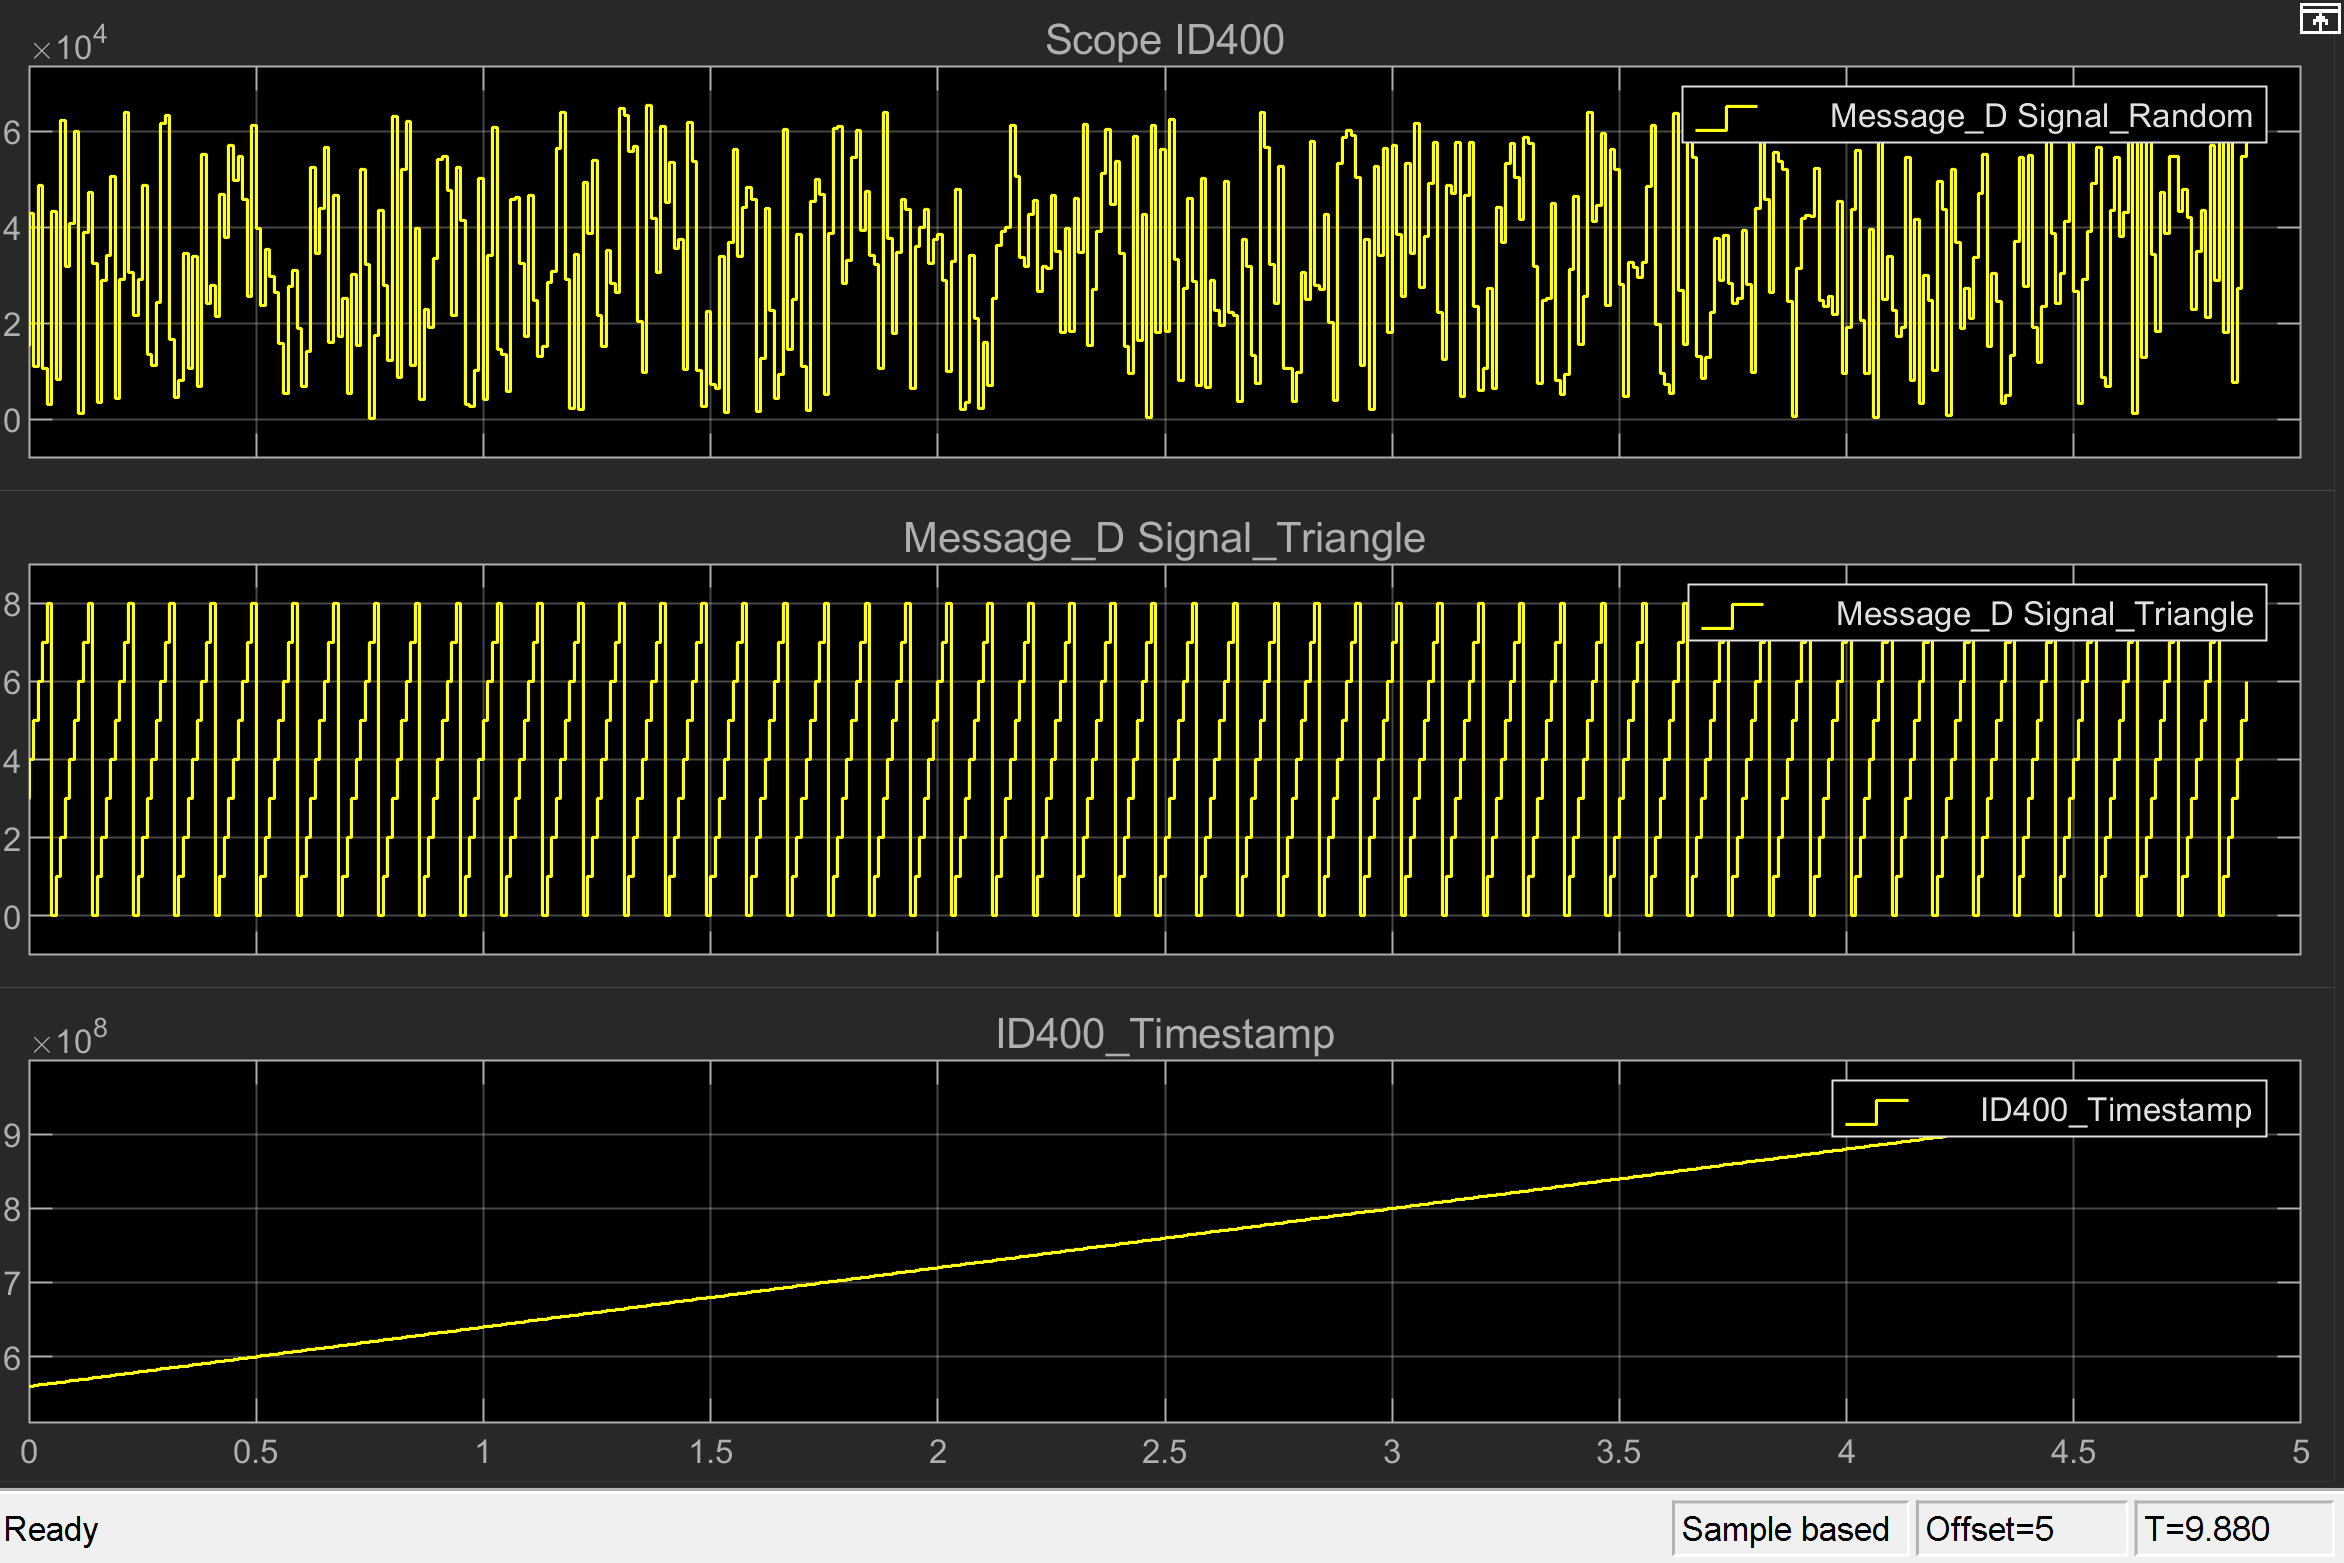

**CAN FD Read Ch2 - standard CAN message **

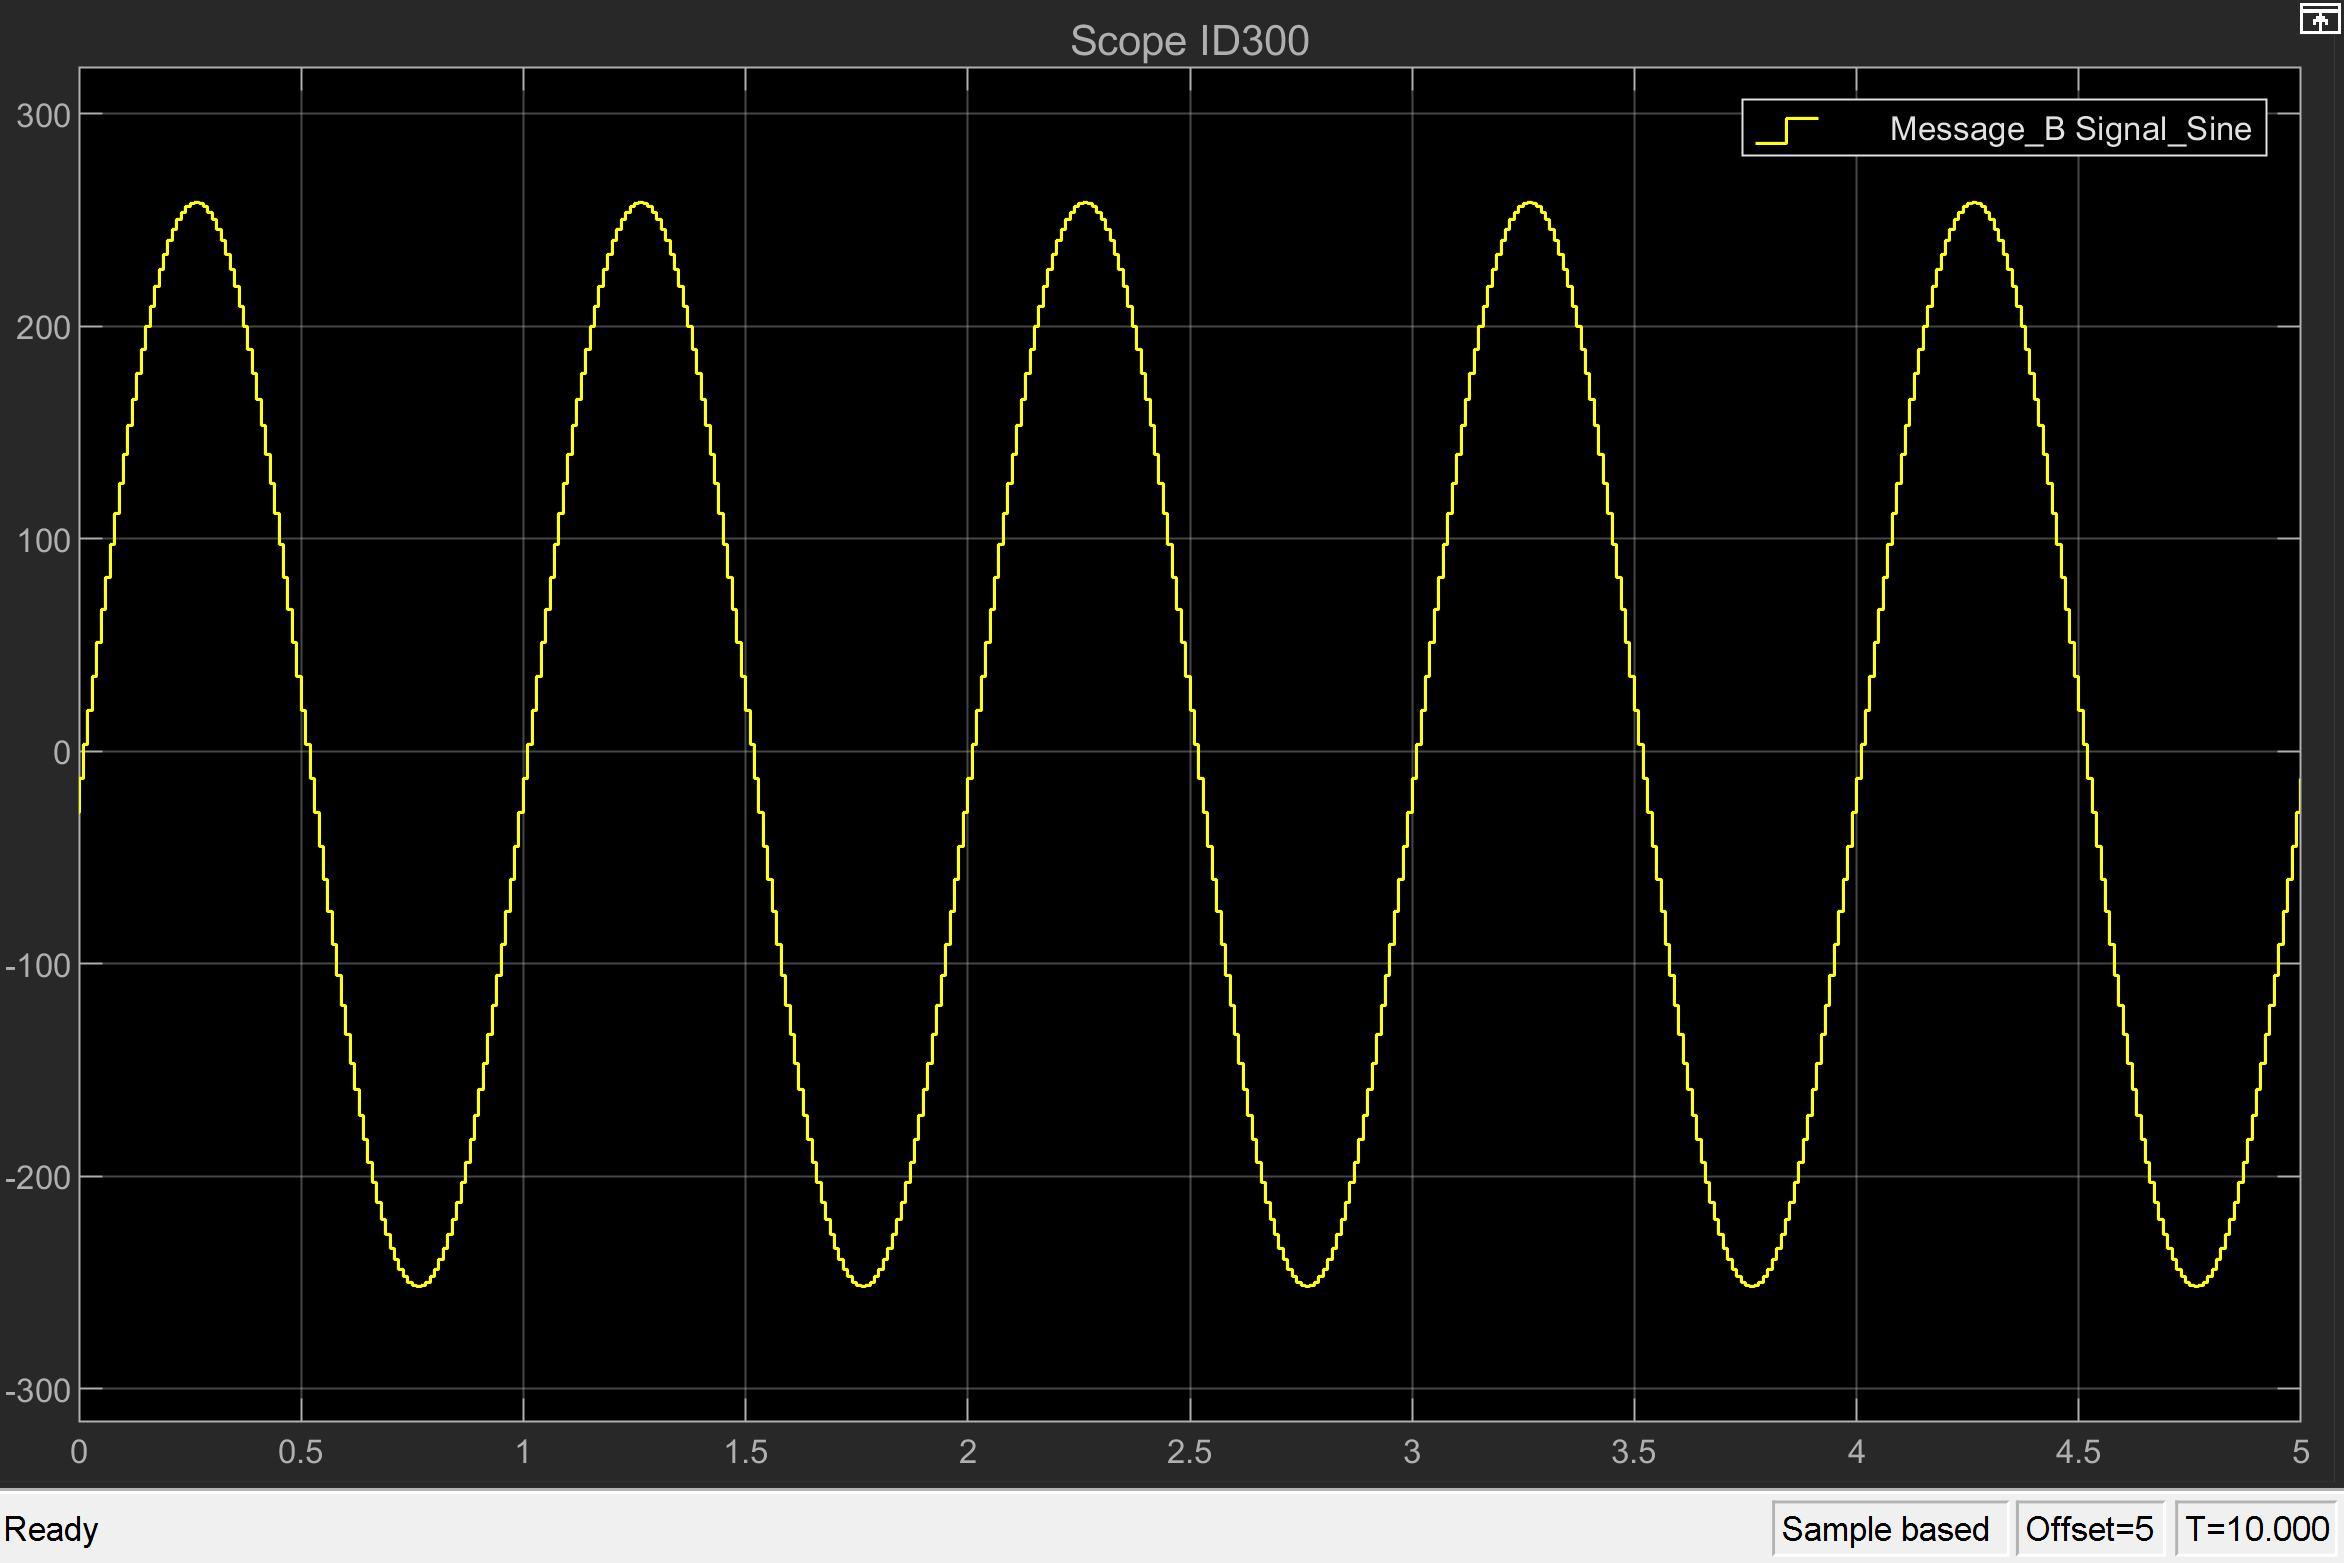 

## Additional References

- [IO602, IO603, IO691 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_can_ofa)